# Práctica 2. Filtros FIR e IIR

#### **Ejercicio 2**. 

Genera 5 segundos de una onda cuadrada de frecuencia 800 Hz, pero representa sólo 0.005 segundos de la misma. Diseña un filtro FIR Hamming para extraer el armónico fundamental. Oye y representa tanto la señal original como la resultante. 

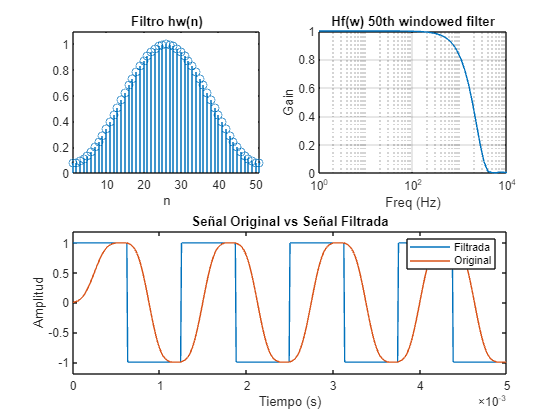

clear all
close all

fs = 100000;
fc = 1000/fs;
fu = 800;
wu = 2*pi*fu;
tiv = 1/fs;
t=0:tiv:(0.005-tiv);
u=square(wu*t);

N = 50;
hw = hamming(N+1);
numd = fir1(N,fc,hw);
dend = 1;

figure (1)
subplot(2,2,1);
stem(hw)
axis([1 51 0 1.1]);
title('Filtro hw(n)')
xlabel('n')
subplot(2,2,2);
f=logspace(0,4);
G=freqz(numd,dend,f,fs);
semilogx(f,abs(G));
grid;
ylabel('Gain')
xlabel('Freq (Hz)')
title('Hf(w) 50th windowed filter')
hold off;
y = filter(numd,dend,u);
subplot(2,2,[3,4])
plot(t,u)
hold on
plot(t,y)
xlim([0 0.005]);
ylim([-1.2 1.2]);
title('Señal Original vs Señal Filtrada')
legend('Filtrada', 'Original')
xlabel('Tiempo (s)')
ylabel('Amplitud')

sound(u,fs);
pause(length(u)/fs);
sound(y,fs);